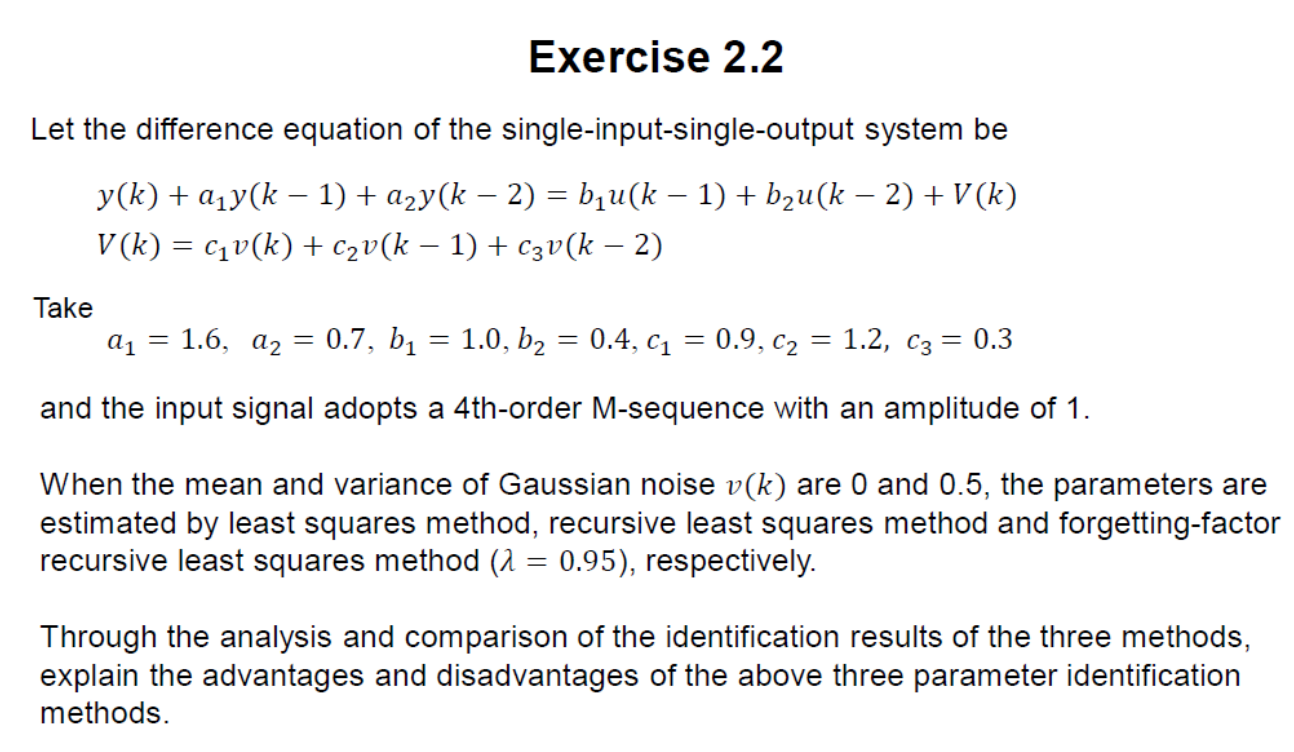

噪声将影响当前的输出。但只有过去的输入才会影响现在的输出。这是一个因果系统

v可测和v不可测  是完全两种不同的情况

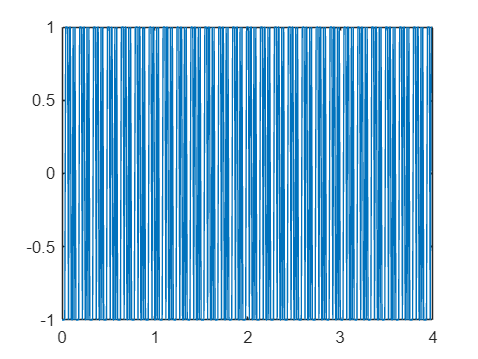

clear 
close all
L = 400;      % 仿真长度
Ts = 0.01;
aTrue = [1.6 0.7];
bTrue = [1.0 0.4 0.5];
cTrue = [0.9 1.2 0.3];


t = 0:Ts:Ts*(L-1);

v = randn(L,1)*0.5;  %PRBS8(t,8,1);
u = PRBS(t,4,1);

plot(t,u)

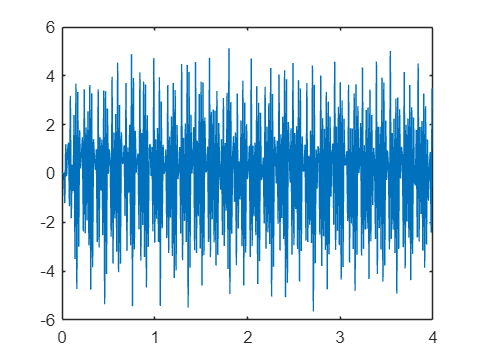


d = 3;
for i = 1:d
    y(i) = 0;
end

for k = 1+d:L
    % if k >= 200
    %     Vk = cTrue(1)*v(k) + cTrue(2)*v(k-1) + cTrue(3)*v(k-2);
    %     y(k) = -aTrue(1)*y(k-1) - aTrue(2)*y(k-2) + bTrue(1)*u(k-1) + bTrue(2)*u(k-2) + bTrue(3)*u(k-3) + Vk;
    % else 
        Vk = cTrue(1)*v(k) + cTrue(2)*v(k-1) + cTrue(3)*v(k-2);
        y(k) = -aTrue(1)*y(k-1) - aTrue(2)*y(k-2) + bTrue(1)*u(k-1) + bTrue(2)*u(k-2) + Vk;
    % end
end

plot(t,y)

`LSM   无法处理噪声v不可测的情况。只能假设噪声可测`

`由于采用vhatk = yk - yhatk = yk - phihat'*thetaE的方式估计噪声，但在一开始时thetaE未知。`

Phi = []; Y = [];

for k = 1+d:L   
    phik = [-y(k-1)  -y(k-2)  u(k-1)  u(k-2) u(k-3) v(k) v(k-1) v(k-2) ]';
    Phi = [Phi;phik'];
    
    Y = [Y;y(k)];
end

thetaLSM = inv(Phi'*Phi)*Phi'*Y

thetaLSM =     1.6000
    0.7000
    1.0000
    0.4000
   -0.0000
    0.9000
    1.2000
    0.3000


## RLSM  无法处理v(k)前系数不为1的情况。

% vk 归一化  vbark = 1/0.9 * vk
% vbar = 1/0.9 .* v;

P = 10^18 * eye(8);
thetaRLSM = zeros(8,1);
vhat = [0 0];

for k = 1+d:L
    phik = [-y(k-1)  -y(k-2)  u(k-1)  u(k-2) u(k-3) v(k) v(k-1) v(k-2) ]';
    % phik = [-y(k-1)  -y(k-2)  u(k-1)  u(k-2)  vhat(k-1) vhat(k-2) ]';   % vhat(k)项的加入将导致收敛到一个错误的值
    K = P*phik/(1+phik'*P*phik);
    P = (eye(8) - K*phik')*P;
    %%%%%% v不可测时
    vk = y(k) - phik'*thetaRLSM;
    vhat = [vhat, vk];
    %%%%%%
    thetaRLSM = thetaRLSM + K *(y(k) - phik'*thetaRLSM);

    thetaRLSMrecord(:,k-d) = thetaRLSM;
end
thetaRLSM

thetaRLSM =     1.6000
    0.7000
    1.0000
    0.4000
   -0.0000
    0.9000
    1.2000
    0.3000


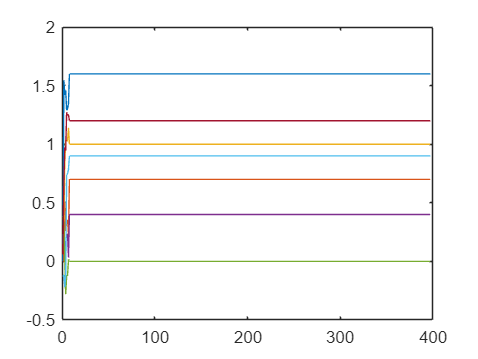

figure,plot(thetaRLSMrecord(1,:)); hold on
plot(thetaRLSMrecord(2,:))
plot(thetaRLSMrecord(3,:))
plot(thetaRLSMrecord(4,:))
plot(thetaRLSMrecord(5,:))
plot(thetaRLSMrecord(6,:))
plot(thetaRLSMrecord(7,:))

## FFRLSM

yMeasured = y;
uMeasured = u;
vMeasured = v;

uInit = [0 0 0];     nb = length(uInit);
yInit = [0 0];     na = length(yInit);
vInit = [0 0];     nc = length(vInit)+1;  % 拥有当前步vk的影响故需要加1

lambda = 0.9;   % 在初值不准确时，采用遗忘因子会有更好的收敛效果
P = 10^10 * eye(na+nb+nc);
thetaFFRLSM = zeros(na+nb+nc,1);

% real controler: 
% y u 都是一步一步获取的。实际中将放在单片机的无限循环里
% input: u(k) y(k) v(k) 当前时刻的测量量(假设都可测)  
%        状态空间A B C的维数  na nb nc   
%        初始状态值：[u(-2) u(-1) u(-0)] [y(-2)...]  [v(-2)...] 
%        初始P矩阵、thetaRLSM
% output: thetaRLSM(k)  当前时刻计算得到的各系数参数
% 重要的中间变量 ukVector ykVector vkVector 记录向前x几个时刻的输入量、输出量、噪声输入量

%  构造第一步时要用到的向量；存在诸如v(k)项时要补齐; 采用左移序列
uk = uInit;
yk = yInit;
vk = [vInit vMeasured(1)];

for k = 1:L-1
    phik = [-fliplr(yk) fliplr(uk) fliplr(vk)]';
    K = P*phik/(lambda+phik'*P*phik);
    P = (eye(na+nb+nc) - K*phik')*P/lambda;
    thetaFFRLSM = thetaFFRLSM + K *(yMeasured(k) - phik'*thetaFFRLSM);

    % 更新 uk yk vk  xk = [x(-2) x(-1) x(0) x(1)]; 
    % 采用左移序列
    for i = 1:nb-1
        uk(i) = uk(i+1);
    end
    uk(nb) = uMeasured(k);
    
    for i = 1:na-1
        yk(i) = yk(i+1);
    end
    yk(na) = yMeasured(k);

    for i = 1:nc-1
        vk(i) = vk(i+1);
    end
    vk(nc) = vMeasured(k+1);   % 需要注意

    % debug
    thetaFFRLSMrecord(:,k) = thetaFFRLSM;
    uk;
    yk;
    vk;
end

thetaFFRLSMrecord(:,190)

ans =     1.6000
    0.7000
    1.0000
    0.4000
    0.0000
    0.9000
    1.2000
    0.3000


thetaFFRLSM

thetaFFRLSM =     1.6000
    0.7000
    1.0000
    0.4000
   -0.0000
    0.9000
    1.2000
    0.3000


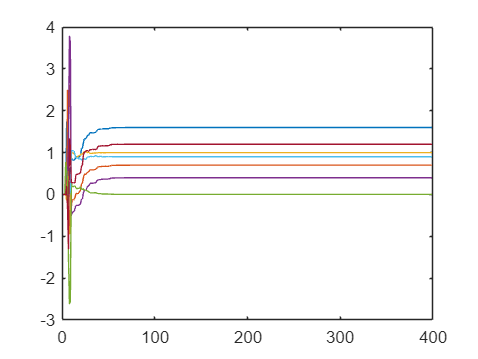


figure,plot(thetaFFRLSMrecord(1,:)); hold on
plot(thetaFFRLSMrecord(2,:))
plot(thetaFFRLSMrecord(3,:))
plot(thetaFFRLSMrecord(4,:))
plot(thetaFFRLSMrecord(5,:))
plot(thetaFFRLSMrecord(6,:))
plot(thetaFFRLSMrecord(7,:))

## FFRLSM  如果v不可测，采用 y(k)-phiHat'*thetaHat 估计v(k) （多次调试未成功）

yMeasured = y;
uMeasured = u;
vMeasured = v;

uInit = [0 0];     nb = length(uInit);  % 需要准确的维度，不然收敛太艰难
yInit = [0 0];     na = length(yInit);
vInit = [0 0];     nc = length(vInit);  % 拥有当前步vk的影响故需要加1

lambda = 0.95;   % 在初值不准确时，采用遗忘因子会有更好的收敛效果
P = 10^5 * eye(na+nb+nc);
thetaFFRLSM = zeros(na+nb+nc,1);

% real controler: 
% y u 都是一步一步获取的。实际中将放在单片机的无限循环里
% input: u(k) y(k) v(k) 当前时刻的测量量(假设都可测)  
%        状态空间A B C的维数  na nb nc   
%        初始状态值：[u(-2) u(-1) u(-0)] [y(-2)...]  [v(-2)...] 
%        初始P矩阵、thetaRLSM
% output: thetaRLSM(k)  当前时刻计算得到的各系数参数
% 重要的中间变量 ukVector ykVector vkVector 记录向前x几个时刻的输入量、输出量、噪声输入量

%  构造第一步时要用到的向量；存在诸如v(k)项时要补齐; 采用左移序列
uk = uInit;
yk = yInit;
% vk = [vInit vMeasured(1)];
vk = [vInit];   % v1 = 0 作为估计。

for k = 1:L-1
    phik = [-fliplr(yk) fliplr(uk) fliplr(vk)]';
    K = P*phik/(lambda+phik'*P*phik);
    P = (eye(na+nb+nc) - K*phik')*P/lambda;
    thetaFFRLSM = thetaFFRLSM + K *(yMeasured(k) - phik'*thetaFFRLSM);

    % 更新 uk yk vk  xk = [x(-2) x(-1) x(0) x(1)]; 
    % 采用左移序列
    for i = 1:nc-1
        vk(i) = vk(i+1);
    end
    % vk(nc) = vMeasured(k+1);   % 需要注意
    vk(nc) = yMeasured(k+1) - phik'*thetaFFRLSM;

    for i = 1:nb-1
        uk(i) = uk(i+1);
    end
    uk(nb) = uMeasured(k);
    
    for i = 1:na-1
        yk(i) = yk(i+1);
    end
    yk(na) = yMeasured(k);

    % debug
    thetaFFRLSMrecord(:,k) = thetaFFRLSM;
    uk;
    yk;
    vk;
end

thetaFFRLSMrecord(:,190)

ans =    -0.6668
   -0.3332
    0.0000
    0.0000
    1.0000
    0.3332


thetaFFRLSM

thetaFFRLSM =     0.0062
   -1.0062
   -0.0000
    0.0000
    1.0000
    1.0062


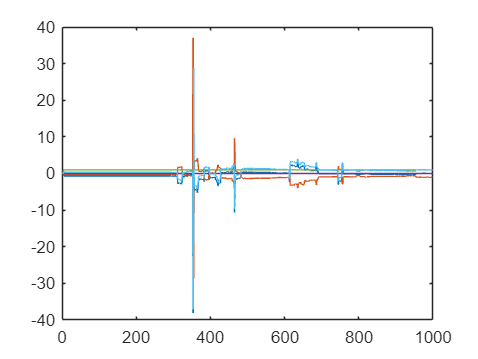


figure,plot(thetaFFRLSMrecord(1,:)); hold on
plot(thetaFFRLSMrecord(2,:))
plot(thetaFFRLSMrecord(3,:))
plot(thetaFFRLSMrecord(4,:))
plot(thetaFFRLSMrecord(5,:))
plot(thetaFFRLSMrecord(6,:))

plot(thetaFFRLSMrecord(7,:))

位置 1 处的索引超出数组边界。索引不能超过 6。

function Out = PRBS(t,n,a)
% a: the altitude of M-sequence, 
% t为生成的时间一共多长
% n用来控制一个PRBS序列的周期长度  一个周期＝2^n-1
% Generate a PRBS signal
% 1. 自相关性尽可能为δ函数（低相关性）。  2. 尽可能均匀分布(接近白噪声）  3. 但又要可被重复实现 
% n=4;                                % the number of registers
% L=15+1;                             % the length of M-sequence to be required   越长越接近白噪声
L = length(t);

for i = 1:n  Reg(i) = 1; end        % Initialize n registers  位移寄存器全1
Out(1)=-a;

for i=2:L
        temp=Reg(1);
        % 注意反馈抽头 可用GPT帮忙写
        % 抽头为第4、5、6、8级，异或结果反馈到第1级  仅适用于n = 8的情况
        % Reg(1) = xor(xor(xor(Reg(4), Reg(5)), Reg(6)), Reg(8)); 
        %%  仅适用于n= 4 5 6 7 9 10 等情况
        Reg(1)=xor(Reg(n-1),Reg(n));  % Modulo 2 adder   第一个寄存器 
        j=2;
        while j<=n                  % Registers shift                
             temp1=Reg(j);
             Reg(j)=temp;
             j=j+1;
             temp=temp1;
        end        
        Out(i)=Reg(n);
        if (Reg(n)==1)  Out(i) =-a; end
        if (Reg(n)==0)  Out(i)=a; end
end   

% stairs(Out); axis([1 L -0.5 1.5]);  % Plot the PRBS signal

end




function Out = PRBS13(t,n,a)
% a: the altitude of M-sequence, 
% t为生成的时间一共多长
% n用来控制一个PRBS序列的周期长度  一个周期＝2^n-1
% Generate a PRBS signal
% 1. 自相关性尽可能为δ函数（低相关性）。  2. 尽可能均匀分布(接近白噪声）  3. 但又要可被重复实现 
% n=4;                                % the number of registers
% L=15+1;                             % the length of M-sequence to be required   越长越接近白噪声
L = length(t);

for i = 1:n  Reg(i) = 1; end        % Initialize n registers  位移寄存器全1
Out(1)=-a;

for i=2:L
        temp=Reg(1);
        % 注意反馈抽头 可用GPT帮忙写
        % 抽头为第4、5、6、8级，异或结果反馈到第1级  仅适用于n = 8的情况
        % Reg(1) = xor(xor(xor(Reg(4), Reg(5)), Reg(6)), Reg(8)); 
        %% n = 13
        Reg(1) = xor(xor(xor(Reg(1), Reg(3)), Reg(4)), Reg(13));
        %%  仅适用于n= 4  情况
        % Reg(1)=xor(Reg(n-1),Reg(n));  % Modulo 2 adder   第一个寄存器 
        j=2;
        while j<=n                  % Registers shift                
             temp1=Reg(j);
             Reg(j)=temp;
             j=j+1;
             temp=temp1;
        end        
        Out(i)=Reg(n);
        if (Reg(n)==1)  Out(i) =-a; end
        if (Reg(n)==0)  Out(i)=a; end
end   

% stairs(Out); axis([1 L -0.5 1.5]);  % Plot the PRBS signal

end


function Out = PRBS8(t,n,a)
% a: the altitude of M-sequence, 
% t为生成的时间一共多长
% n用来控制一个PRBS序列的周期长度  一个周期＝2^n-1
% Generate a PRBS signal
% 1. 自相关性尽可能为δ函数（低相关性）。  2. 尽可能均匀分布(接近白噪声）  3. 但又要可被重复实现 
% n=4;                                % the number of registers
% L=15+1;                             % the length of M-sequence to be required   越长越接近白噪声
L = length(t);

for i = 1:n  Reg(i) = 1; end        % Initialize n registers  位移寄存器全1
Out(1)=-a;

for i=2:L
        temp=Reg(1);
        % 注意反馈抽头 可用GPT帮忙写
        % 抽头为第4、5、6、8级，异或结果反馈到第1级  仅适用于n = 8的情况
        Reg(1) = xor(xor(xor(Reg(4), Reg(5)), Reg(6)), Reg(8)); 
        %% n = 13
        % Reg(1) = xor(xor(xor(Reg(1), Reg(3)), Reg(4)), Reg(13));
        %%  仅适用于n= 4  情况
        % Reg(1)=xor(Reg(n-1),Reg(n));  % Modulo 2 adder   第一个寄存器 
        j=2;
        while j<=n                  % Registers shift                
             temp1=Reg(j);
             Reg(j)=temp;
             j=j+1;
             temp=temp1;
        end        
        Out(i)=Reg(n);
        if (Reg(n)==1)  Out(i) =-a; end
        if (Reg(n)==0)  Out(i)=a; end
end   

% stairs(Out); axis([1 L -0.5 1.5]);  % Plot the PRBS signal

end